clear

% EDIT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load("../mat/line_extracted.mat");
load("../mat/data.mat");

threshold = 1.5;
map_y =0.8;         % intensity of yellow at 0
map_rb = 0.2;       % intensity of red and blue at threshold

data = data_div_log2_ht_m_div_by_ht_f;
loc = 140;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

maximum_value = max(max(max(data)))

maximum_value = single
0.2489

minimum_value = min(min(min(data)))

minimum_value = single
-1.2276


data_bg = isnan(data);
data_line = line;
data = (data + threshold) / (2 * threshold);
color_map = customcolormap([0 0.5 1], [1 map_rb map_rb; 1 1 map_y; map_rb map_rb 1]);

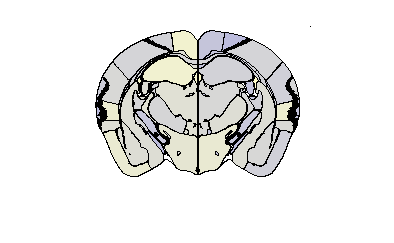

img = ind2rgb(im2uint8(data(:,:,265-loc)), color_map);

img(repmat(data_bg(:,:,265-loc), [1 1 3])) = 1;
img(repmat(logical(data_line(:,:,265-loc)), [1 1 3])) = 0;

imshow(imrotate(img,90));

% colorbar
% axis off